# **PROJECT 1**

**SHANI PINHAS 206658601**

**Guy Cohen 315090712**

# **1.CATALYST DYNAMICS**

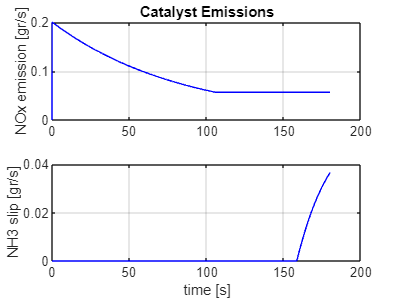

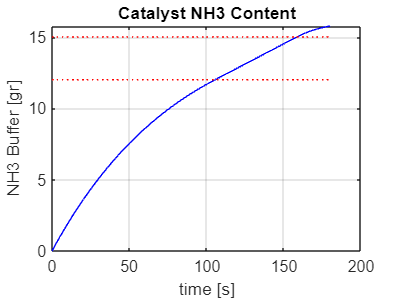

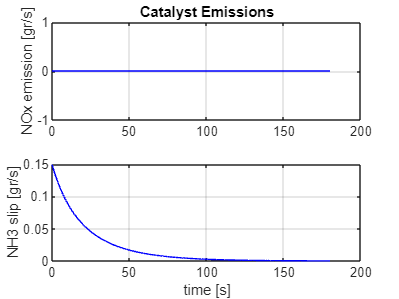

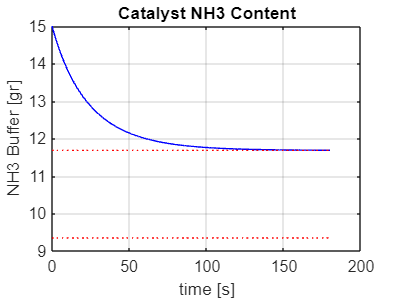

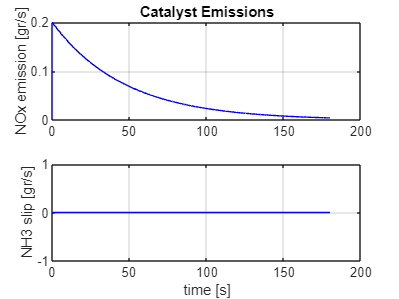

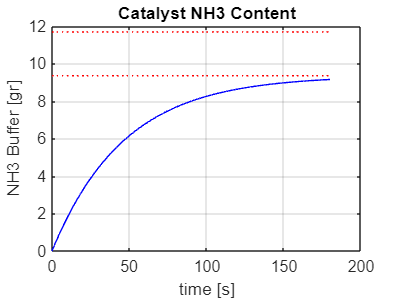

clear all 
% Initialize parameters for VTC thermal model
close all;


% טוען את הקובץ
load('catalystModel.mat');

% משתנים ראשוניים
s = 1;  % אינדקס עבור הגרפים
Tinit = [190, 220, 220];  % טמפרטורות ההתחלה
Xint = [0, 15, 0];        % מצבים התחלתיים

timeStep = 0.1;              % צעד זמן
totalTime = 180;             % זמן כולל
numSteps = totalTime / timeStep;  % מספר צעדים

% וקטורים קבועים לאורך הזמן
emf = 0.1 * ones(1, numSteps);        % זרימת מסה
inNOx = 0.2 * ones(1, numSteps);      % זרם NOx
inNH3_demand = 0.2 * ones(1, numSteps);  % דרישת NH3

% לולאה עבור כל סט פרמטרים
for i = 1:length(Tinit)

    % איפוס המודל
    CatalystModel.reset(Xint(i), Tinit(i), totalTime);

    % יצירת וקטור הטמפרטורה עבור כל צעד בזמן
    T = Tinit(i) * ones(1, numSteps);

    % לולאה של צעדי המודל
    for j = 1:numSteps
        CatalystModel.makeStep(emf(j), T(j), inNOx(j), inNH3_demand(j));
    end

    % הדפסת ערך s לפני כל גרף

    % ציור גרפים
    CatalystModel.plotBufferEmissions(s);
    CatalystModel.plotBufferState(s + 1);

    s = s + 2;

    % קבלת הלוגים
    CatalystLog = CatalystModel.getLogs;
end

# **1.2 MINIMIZE EMISSIONS**

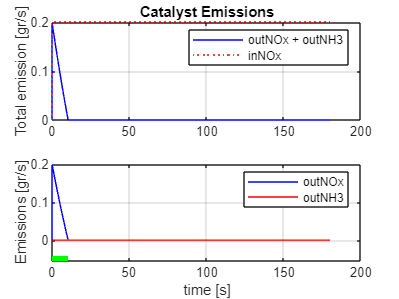

clear all 
close all;

% טוען את הקובץ
load('catalystModel.mat');

timeStep = 0.1;              % צעד זמן
totalTime = 180;              % זמן כולל
numSteps = totalTime / timeStep;  % מספר צעדים

% וקטורים קבועים לאורך הזמן
emf = 0.1 * ones(1, numSteps);       % הגדרת emf כקבוע
inNOx = 0.2 * ones(1, numSteps);     % זרם NOx

Tincr_demand = 0 * ones(1, numSteps);
for i = 1:numSteps
    % If the time is less than 3 minutes, set ∆Tdem to 0°C
    if i * timeStep < 13
        inNH3_demand(i) =1;        % ∆Tdem = 0°C
    else
        inNH3_demand(i) = 0.2;      % ∆Tdem = 120°C
    end
end

%inNH3_demand = 13 * ones(1, numSteps);

%inNH3_demand(1:13) = 1;                 % הגדרת הערכים עבור 13 הצעדים הראשונים
%inNH3_demand(13: numSteps) = 0.2; 
T = 220 * ones(1, numSteps);           % טמפרטורה קבועה

% אתחול המודל
CatalystModel.reset(0, 220, totalTime);

% סימולציה
for j = 1:numSteps
    CatalystModel.makeStep(emf(j), T(j), inNOx(j), inNH3_demand(j));
end

% גרפים
CatalystModel.plotEmissionsReduction(1);

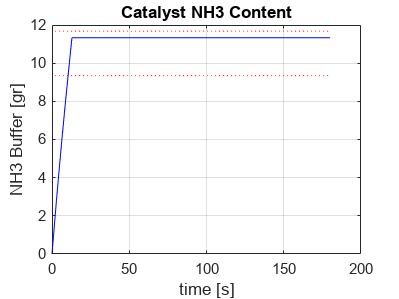

CatalystModel.plotBufferState(2);

# **2.1TERMO_1_a**

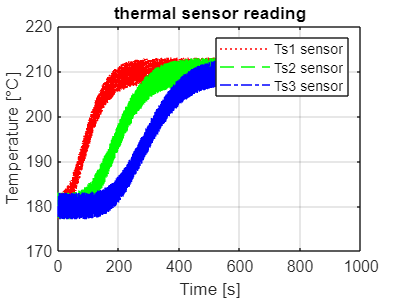

%מקרה 1
clear all 
% Initialize parameters for VTC thermal model
close all;

% Load the VTC thermal model (assumed to be available in the 'ThermalModel.mat' file)
load('ThermalModel.mat');

% Simulation parameters
timeStep = 0.1;                  % Time step in seconds
totalTime = 15 * 60;             % Total time (15 minutes = 900 seconds)
numSteps = totalTime / timeStep; % Number of simulation steps

% Constant values for the simulation
emf = 0.1 * ones(1, numSteps);      % Constant exhaust mass flow [kg/s]
Texh = 210 * ones(1, numSteps);     % Constant exhaust temperature [°C]
Tincr_demand = 0 * ones(1, numSteps); % Constant temperature demand change [°C]
Tinit = 180;                       % Initial temperature of the muffler [°C]

% Initialize the model (reset the model with initial conditions)
ThermalModel.reset(Tinit, totalTime);

% Run the simulation over the specified time period
for i = 1:numSteps
    % Run the VTC simulation step
    ThermalModel.makeStep(emf(i), Texh(i), Tincr_demand(i));  
end

% Get the logged data from the thermal model after the simulation
ThermalLog = ThermalModel.getLogs;                  % Get logged data from the simulation

% Plot the results: Temperature changes over time
figure
plot(ThermalLog.t, ThermalLog.Ts1, 'r:', 'DisplayName', 'Ts1 sensor')  % Ts1 temperature [°C]
hold on
plot(ThermalLog.t, ThermalLog.Ts2, 'g--', 'DisplayName', 'Ts2 sensor') % Ts2 temperature [°C]
plot(ThermalLog.t, ThermalLog.Ts3, 'b-.', 'DisplayName', 'Ts3 sensor') % Ts3 temperature [°C]
hold off

% Labels and legends
ylabel('Temperature [°C]')
xlabel('Time [s]')
title ('thermal sensor reading');
legend show
grid on

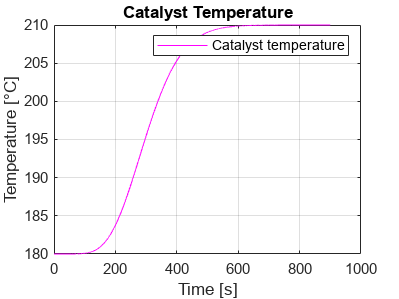


% Plot the catalyst temperature in a separate graph
figure
plot(ThermalLog.t, ThermalLog.Tcatalyst, 'm-', 'DisplayName', 'Catalyst temperature') % Catalyst temperature
ylabel('Temperature [°C]')
xlabel('Time [s]')
title('Catalyst Temperature');
legend show
grid on

# **2.1TERMO_1_b**

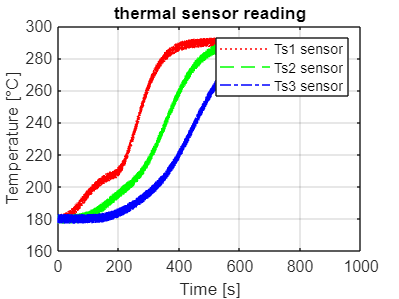


% Initialize parameters for VTC thermal model
close all;

% Load the VTC thermal model (assumed to be available in the 'ThermalModel.mat' file)
load('ThermalModel.mat');

% Simulation parameters
timeStep = 0.1;                  % Time step in seconds
totalTime = 15 * 60;             % Total time (15 minutes = 900 seconds)
numSteps = totalTime / timeStep; % Number of simulation steps

% Constant values for the simulation
emf = 0.1 * ones(1, numSteps);      % Constant exhaust mass flow [kg/s]
Texh = 210 * ones(1, numSteps);     % Constant exhaust temperature [°C]
Tincr_demand = zeros(1, numSteps);  % Initialize temperature demand change array [°C]
Tinit = 180;                        % Initial temperature of the muffler [°C]


% Adjust the temperature demand (∆Tdem) based on the time
for i = 1:numSteps
    % If the time is less than 3 minutes, set ∆Tdem to 0°C
    if i * timeStep < 180
        Tincr_demand(i) = 0;        % ∆Tdem = 0°C
    else
        Tincr_demand(i) = 120;      % ∆Tdem = 120°C
    end
end

% Initialize the model (reset the model with initial conditions)
ThermalModel.reset(Tinit, totalTime);

% Run the simulation over the specified time period
for i = 1:numSteps
    % Run the VTC simulation step
    ThermalModel.makeStep(emf(i), Texh(i), Tincr_demand(i));  
end

% Get the logged data from the thermal model after the simulation
ThermalLog = ThermalModel.getLogs;                  % Get logged data from the simulation

% Plot the results: Temperature changes over time
figure
plot(ThermalLog.t, ThermalLog.Ts1, 'r:', 'DisplayName', 'Ts1 sensor')  % Ts1 temperature [°C]
hold on
plot(ThermalLog.t, ThermalLog.Ts2, 'g--', 'DisplayName', 'Ts2 sensor') % Ts2 temperature [°C]
plot(ThermalLog.t, ThermalLog.Ts3, 'b-.', 'DisplayName', 'Ts3 sensor') % Ts3 temperature [°C]
hold off

% Labels and legends
title ('thermal sensor reading');
ylabel('Temperature [°C]')
xlabel('Time [s]')
legend show
grid on

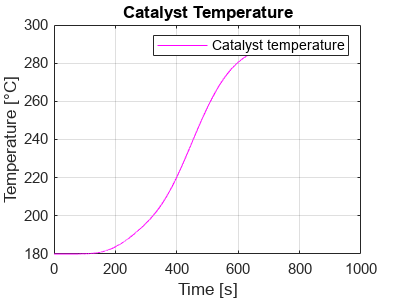


% Plot the catalyst temperature in a separate graph
figure
plot(ThermalLog.t, ThermalLog.Tcatalyst, 'm-', 'DisplayName', 'Catalyst temperature') % Catalyst temperature
ylabel('Temperature [°C]')
xlabel('Time [s]')
title('Catalyst Temperature');
legend show
grid on

# **2.2TERMO_2**

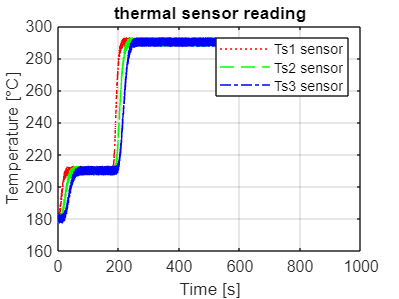



% Initialize parameters for VTC thermal model
close all;

% Load the VTC thermal model (assumed to be available in the 'ThermalModel.mat' file)
load('ThermalModel.mat');

% Simulation parameters
timeStep = 0.1;                  % Time step in seconds
totalTime = 15 * 60;             % Total time (15 minutes = 900 seconds)
numSteps = totalTime / timeStep; % Number of simulation steps

% Constant values for the simulation
emf = 0.8 * ones(1, numSteps);      % Constant exhaust mass flow [kg/s]
Texh = 210 * ones(1, numSteps);     % Constant exhaust temperature [°C]
Tincr_demand = zeros(1, numSteps);  % Initialize temperature demand change array [°C]
Tinit = 180;                        % Initial temperature of the muffler [°C]


% Adjust the temperature demand (∆Tdem) based on the time
for i = 1:numSteps
    % If the time is less than 3 minutes, set ∆Tdem to 0°C
    if i * timeStep < 180
        Tincr_demand(i) = 0;        % ∆Tdem = 0°C
    else
        Tincr_demand(i) = 120;      % ∆Tdem = 120°C
    end
end

% Initialize the model (reset the model with initial conditions)
ThermalModel.reset(Tinit, totalTime);

% Run the simulation over the specified time period
for i = 1:numSteps
    % Run the VTC simulation step
    ThermalModel.makeStep(emf(i), Texh(i), Tincr_demand(i));  
end

% Get the logged data from the thermal model after the simulation
ThermalLog = ThermalModel.getLogs;                  % Get logged data from the simulation

% Plot the results: Temperature changes over time
figure
plot(ThermalLog.t, ThermalLog.Ts1, 'r:', 'DisplayName', 'Ts1 sensor')  % Ts1 temperature [°C]
hold on
plot(ThermalLog.t, ThermalLog.Ts2, 'g--', 'DisplayName', 'Ts2 sensor') % Ts2 temperature [°C]
plot(ThermalLog.t, ThermalLog.Ts3, 'b-.', 'DisplayName', 'Ts3 sensor') % Ts3 temperature [°C]
hold off

% Labels and legends
title ('thermal sensor reading');
ylabel('Temperature [°C]')
xlabel('Time [s]')
legend show
grid on

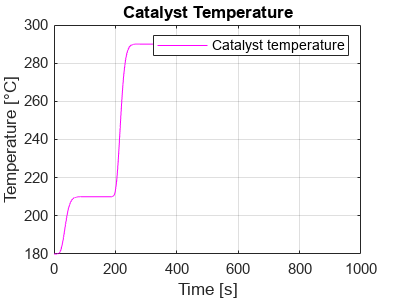


% Plot the catalyst temperature in a separate graph
figure
plot(ThermalLog.t, ThermalLog.Tcatalyst, 'm-', 'DisplayName', 'Catalyst temperature') % Catalyst temperature
ylabel('Temperature [°C]')
xlabel('Time [s]')
title('Catalyst Temperature');
legend show
grid on


%%T

# **3.1overall emmision dynamics**

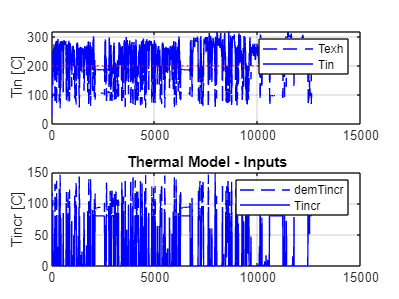

% Initialize parameters for joint VTC catalyst and thermal model simulation
close all;

% Load the necessary models and input data
load('CatalystModel.mat');  
load('ThermalModel.mat');     
load('InputData_Cycle1.mat');

% Extract data from the struct
time = InputData.time;       % Time
emf = InputData.emf;         % Gas flow
Texh = InputData.Texh;       % Exhaust temperature
inNOx = InputData.eoNOx;     % NOx flow

numSteps = length(time);  % Number of simulation steps based on the time vector

% Initialize control signals (∆Tdem and inNH3_demand)
Tincr_demand = zeros(1, numSteps);  % ∆Tdem = 0 initially
inNH3_demand = zeros(1, numSteps);  % NH3 demand initially set to 0

% 
CatalystModel.reset(0,25,900);
ThermalModel.reset(25,900);

T_limit = 200;
Tincr_demand = zeros(1, numSteps);  % Initialize temperature increment demand
% ההפרש חייב להיות אי שלילי
for i = 1:numSteps-1
    if Texh(i) >= T_limit
        Tincr_demand(i) = 0;  % No temperature adjustment needed
    else
        Tincr_demand(i) = T_limit - Texh(i);  % Demand to increase temperature
    end


    % Update ∆Tdem
    inNH3_demand(i) = inNOx(i);

    ThermalModel.makeStep(emf(i), Texh(i), Tincr_demand(i));  
    ThermalValues = ThermalModel.getCurrentValues;
    CatalystModel.makeStep(emf(i),ThermalValues.Tcatalyst,inNOx(i),inNH3_demand(i));
end


iFig = 14;
Tlim = 200;
iFig = ThermalModel.plotInputs(iFig,Tlim);

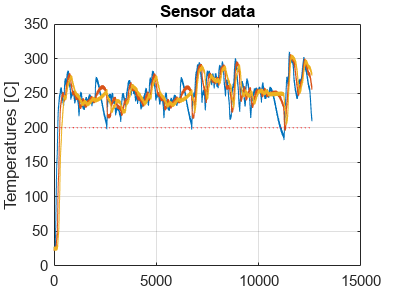

iFig = ThermalModel.plotSensorData(iFig,Tlim);

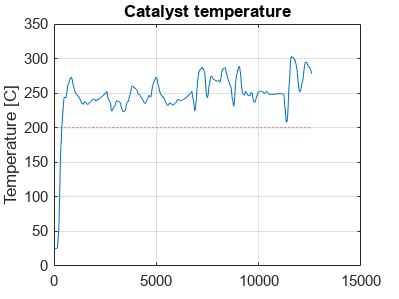

iFig = ThermalModel.plotCatalystTemperature(iFig,Tlim);

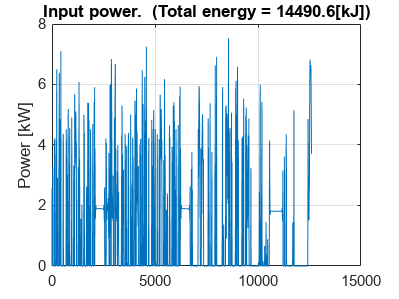

iFig = ThermalModel.plotPower(iFig);

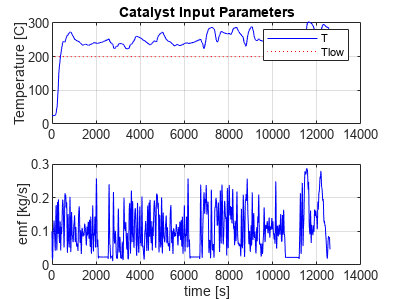

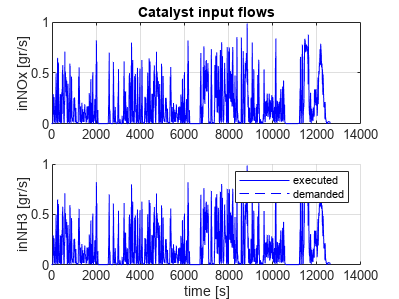

iFig = CatalystModel.plotBufferInputs(iFig);

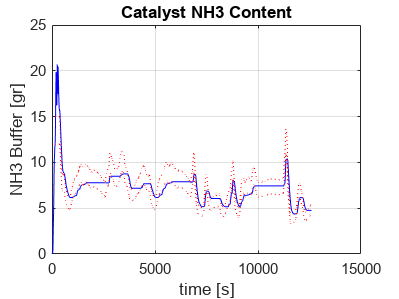

iFig = CatalystModel.plotBufferState(iFig);

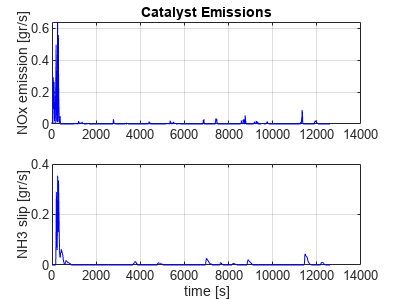

iFig = CatalystModel.plotBufferEmissions(iFig);

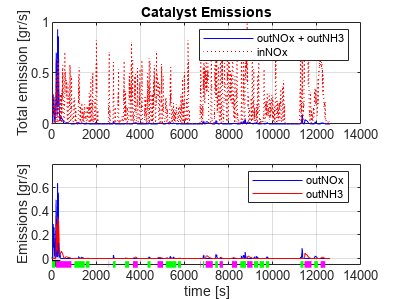

iFig = CatalystModel.plotEmissionsReduction(iFig);

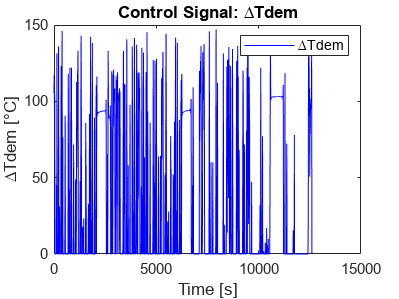







% Plot control signals (∆Tdem and inNH3_demand)
figure
plot(time, Tincr_demand, 'b-', 'DisplayName', '∆Tdem');
ylabel('∆Tdem [°C]');
xlabel('Time [s]');
legend show;
title('Control Signal: ∆Tdem');
hold off

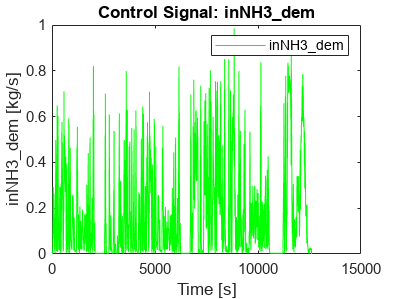


figure
plot(time, inNH3_demand, 'g-', 'DisplayName', 'inNH3\_dem');
ylabel('inNH3\_dem [kg/s]');
xlabel('Time [s]');
legend show;
title('Control Signal: inNH3\_dem');
hold off

# **4.1.a FINDING ALPHA**

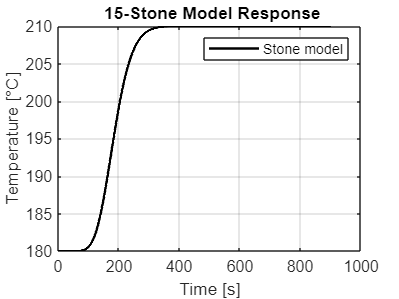


% מודל 15 אבנים
alpha = 0.8;  % פרמטר alpha
emf = 0.1;  % emf

T_exh = 210;  % טמפרטורת האוורור
T_sim = 900;  % זמן סימולציה [שניות]
T0 = 180;  % טמפרטורה התחלתית

% הגדרת פונקציית העברה עבור אבן אחת
s = tf('s');
stone_tf  = (1 / ((1 / (alpha * emf)) * s + 1))^15;

% המרת פונקציית העברה למערכת במרחב מצב
%stone_ss = ss(stone_tf);
%stone_ss.D = 1;  % הגדרת רכיב D

% הגדרת זמן הסימולציה
time = 0:0.1:900;  % וקטור זמן [שניות]
%input_signal = ThermalModel.Ts1_log(1:length(time));  % קלט טמפרטורת סנסור 1 (בהנחה שזה נתון)
input_signal = ones(size(time)) * (T_exh - T0);

% שימוש ב- lsim עם תנאי התחלה
[T_response, T_time] = lsim(stone_tf, input_signal, time);  % הרצת הסימולציה עם תנאי התחלה
T_response=T_response+T0;
% הצגת התוצאה - תגובת המערכת לטמפרטורת סנסור 1
plot(T_time, T_response, 'k-', 'LineWidth', 1.5, 'DisplayName', '15-Stone Model Response');

% כותרות וערכים עבור הגרף
xlabel('Time [s]');
ylabel('Temperature [°C]');
title(' 15-Stone Model Response');
legend('Stone model');
grid on;
hold off

# **4.1.b FINDING ALPHA**

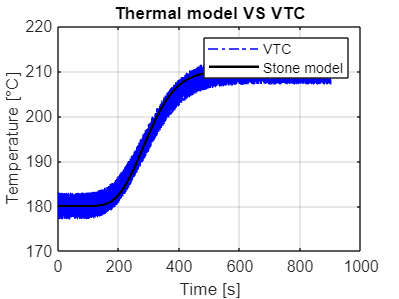

% סנסור 3 מתוך VTC
%מקרה 1
clear all 
% Initialize parameters for VTC thermal model
close all;

% Load the VTC thermal model (assumed to be available in the 'ThermalModel.mat' file)
load('ThermalModel.mat');

% Simulation parameters
timeStep = 0.1;                  % Time step in seconds
totalTime = 15 * 60;             % Total time (15 minutes = 900 seconds)
numSteps = totalTime / timeStep; % Number of simulation steps

% Constant values for the simulation
emf = 0.1 * ones(1, numSteps);      % Constant exhaust mass flow [kg/s]
Texh = 210 * ones(1, numSteps);     % Constant exhaust temperature [°C]
Tincr_demand = 0 * ones(1, numSteps); % Constant temperature demand change [°C]
Tinit = 180;                       % Initial temperature of the muffler [°C]

% Initialize the model (reset the model with initial conditions)
ThermalModel.reset(Tinit, totalTime);

% Run the simulation over the specified time period
for i = 1:numSteps
    % Run the VTC simulation step
    ThermalModel.makeStep(emf(i), Texh(i), Tincr_demand(i));  
end

% Get the logged data from the thermal model after the simulation
ThermalLog = ThermalModel.getLogs;                  % Get logged data from the simulation
plot(ThermalLog.t, ThermalLog.Ts3, 'b-.', 'DisplayName', 'Ts3 sensor') % Ts3 temperature [°C]
hold on



% מודל 15 אבנים
alpha = 0.5;  % פרמטר alpha
emf = 0.1;  % emf

T_exh = 210;  % טמפרטורת האוורור
T_sim = 900;  % זמן סימולציה [שניות]
T0 = 180;  % טמפרטורה התחלתית

% הגדרת פונקציית העברה עבור אבן אחת
s = tf('s');
stone_tf  = (1 / ((1 / (alpha * emf)) * s + 1))^15;


% הגדרת זמן הסימולציה
time = 0:0.1:900;  % וקטור זמן [שניות]
input_signal = ones(size(time)) * (T_exh - T0);

% שימוש ב- lsim עם תנאי התחלה
[T_response, T_time] = lsim(stone_tf, input_signal, time);  % הרצת הסימולציה עם תנאי התחלה
T_response=T_response+T0;
plot(T_time, T_response, 'k-', 'LineWidth', 1.5, 'DisplayName', '15-Stone Model Response');

% כותרות וערכים עבור הגרף
xlabel('Time [s]');
ylabel('Temperature [°C]');
title(' 15-Stone Model Response');
legend('Stone model');
grid on;
title ('Thermal model VS VTC')
legend('VTC','Stone model');
grid on;

# 4.3 FINDING A,B MATRIX 

% Initialize symbolic variables
%syms emf alpha Tin real  % Add Tin as symbolic variable
num_stones = 15;         % Number of stones
emf =0.1;
alpha =0.04;
% Initialize symbolic matrices
A = sym(zeros(num_stones, num_stones)); % State transition matrix
B = sym(zeros(num_stones, 1));          % Input matrix

% Build the A matrix
for i = 1:num_stones
    if i == 1
        A(i, i) = -alpha * emf;          % Self term for T1
    else
        A(i, i) = -alpha * emf;          % Self term for Ti
        A(i, i-1) = alpha * emf;         % Coupling from Ti-1
    end
end

% Build the B matrix (effect of Tin)
B(1) = alpha * emf;  % Only the first stone is directly affected by Tin

% Display symbolic matrices
disp('Matrix A (symbolic):');

Matrix A (symbolic):


disp(A);

$$\left(\begin{array}{ccccccccccccccc} -\frac{1}{250} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{250} & -\frac{1}{250} \end{array}\right)$$


disp('Matrix B (symbolic):');

Matrix B (symbolic):


disp(B);

$$\left(\begin{array}{c} \frac{1}{250}\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$


% Define the state-space representation
%X_dot = A * sym('X', [num_stones, 1]) + B * Tin;  % Symbolic state-space equation



# 4.4 FINDING Ad,Bd DISCRIT MATRIX 


% Parameters
alpha = 0.5;              % Example value for alpha
emf = 0.1;                % Numeric value for emf
num_stones = 15;          % Number of stones
Ts = 5;                % Example sampling time for discretization

% Define symbolic A and B matrices
A = sym(zeros(num_stones, num_stones));
B = sym(zeros(num_stones, 1));

% Build the continuous-time A matrix
for i = 1:num_stones
    if i == 1
        A(i, i) = -alpha * emf;          % Self term for T1
    else
        A(i, i) = -alpha * emf;          % Self term for Ti
        A(i, i-1) = alpha * emf;         % Coupling from Ti-1
    end
end

% Build the continuous-time B matrix
B(1) = alpha * emf;  % Only the first stone is affected by Tin

% Compute the discrete-time matrices
A_d = expm(A * Ts);  % Discretize A using matrix exponential
B_d = simplify((expm(A * Ts) - eye(num_stones)) / A * B);  % Discretize B

% Convert symbolic matrices to numeric
A_d_numeric = vpa(A_d, 10);  % 10 digits of precision
B_d_numeric = vpa(B_d, 10);  % 10 digits of precision

% Display the results
disp('Discrete-time matrix A_d (numeric):');

Discrete-time matrix A_d (numeric):


disp(A_d_numeric);


disp('Discrete-time matrix B_d (numeric):');

Discrete-time matrix B_d (numeric):


disp(B_d_numeric);

$$\left(\begin{array}{c} 0.2211992169\\ 0.02649902116\\ 0.00216149669\\ 0.0001333696505\\ 0.000006611710561\\ 0.0000002738135634\\ 0.000000009734521814\\ 0.0000000003031274728\\ 8.396399895e-12\\ 2.094244916e-13\\ 4.749672877e-15\\ 1.006139616e-16\\ 1.734723476e-18\\ 0\\ 0 \end{array}\right)$$

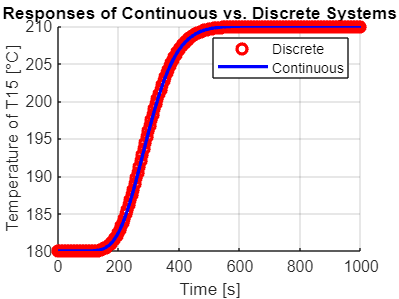

% Parameters
alpha = 0.5;            % Example value for alpha
emf = 0.1;              % Numeric value for emf
num_stones = 15;        % Number of stones
Ts = 5;                 % Sampling time for discretization
total_time = 1000;      % Total simulation time
time = 0:Ts:total_time; % Time vector for simulation

% Define T_exh and T0
T_exh = 210;            % Example value for T_exh (exhaust temperature)
T0 = 180;               % Example value for T0 (initial temperature)

% Step input (difference between T_exh and T0)
input_signal = ones(size(time)) * (T_exh - T0); % Step signal

% Continuous-time matrices
A1 = -alpha * emf * eye(num_stones);
for i = 2:num_stones
    A1(i, i-1) = alpha * emf;  % Coupling from Ti-1
end
B1 = [alpha * emf; zeros(num_stones-1, 1)];

% Initial condition (temperature starts at 180 degrees for all stones)
X0 = T0 * ones(num_stones, 1);  % Initial condition for all stones

% State-space system (Continuous)
sys1 = ss(A1, B1, eye(num_stones), zeros(num_stones, 1));  % Continuous system

% Convert to discrete system
sys2 = c2d(sys1, Ts, 'zoh');  % Discrete system using Zero-Order Hold

% Step response for continuous and discrete systems
[y1, t1] = step(sys1, time);  % Continuous response
[y2, t2] = step(sys2, time);  % Discrete response

% Shift the response to start from T0
y1 = y1 * (T_exh - T0) + T0; % Scale the response to match the step and add the initial value
y2 = y2 * (T_exh - T0) + T0; % Scale the response to match the step and add the initial value

% Plot the step responses for the 15th stone (T15)
figure;
hold on;
stairs(t2, y2(:, 15), 'ro', 'LineWidth', 2);  % Discrete graph for T15
title('Step Responses of Continuous vs. Discrete Systems for T15');
plot(t1, y1(:, 15), 'b', 'LineWidth', 2);  % Continuous graph for T15

xlabel('Time [s]');
ylabel('Temperature of T15 [°C]');
legend('Discrete','Continuous');
grid on;
hold off;